# WEC to spring-mass-damper

How realistic can it be to capture the dynamics of a WEC as a spring-mass-damper?

## Import and check data

This example uses data collected during a wave tank test conducted in 2019 by Sandia National Laboratories at the Navy's Manuevering and Sea Keeping (MASK) basin [1]. In this experiment, the WEC is forced by an actuator in heave at a frequency of 0.6 Hz - no waves are present in the basin.

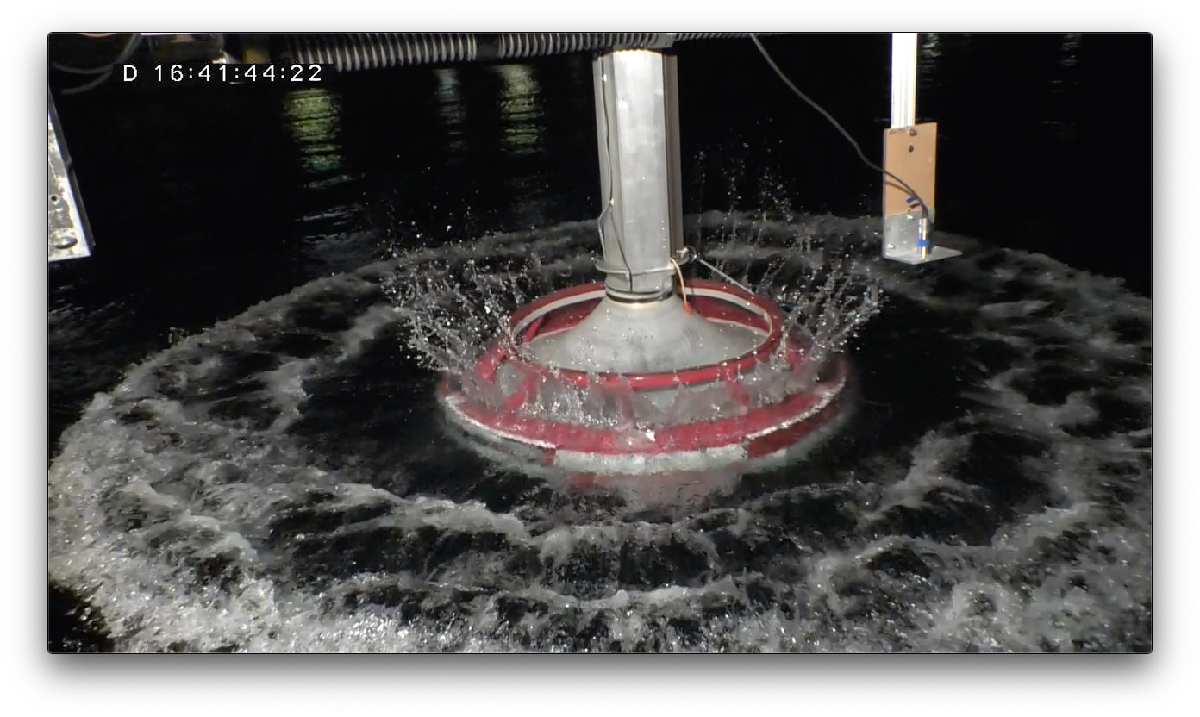

clc
clear

T = 1/0.6; % period of exctiation
mfile = matfile('example_wecToSmd.mat');
wave_tank_data = mfile.wave_tank_data

wave_tank_data =

Time domain data set with 13334 samples.
Sample time: 0.001 seconds               
                                         
Outputs        Unit (if specified)       
   Velocity                              
                                         
Inputs         Unit (if specified)       
   Force                                 
                                         


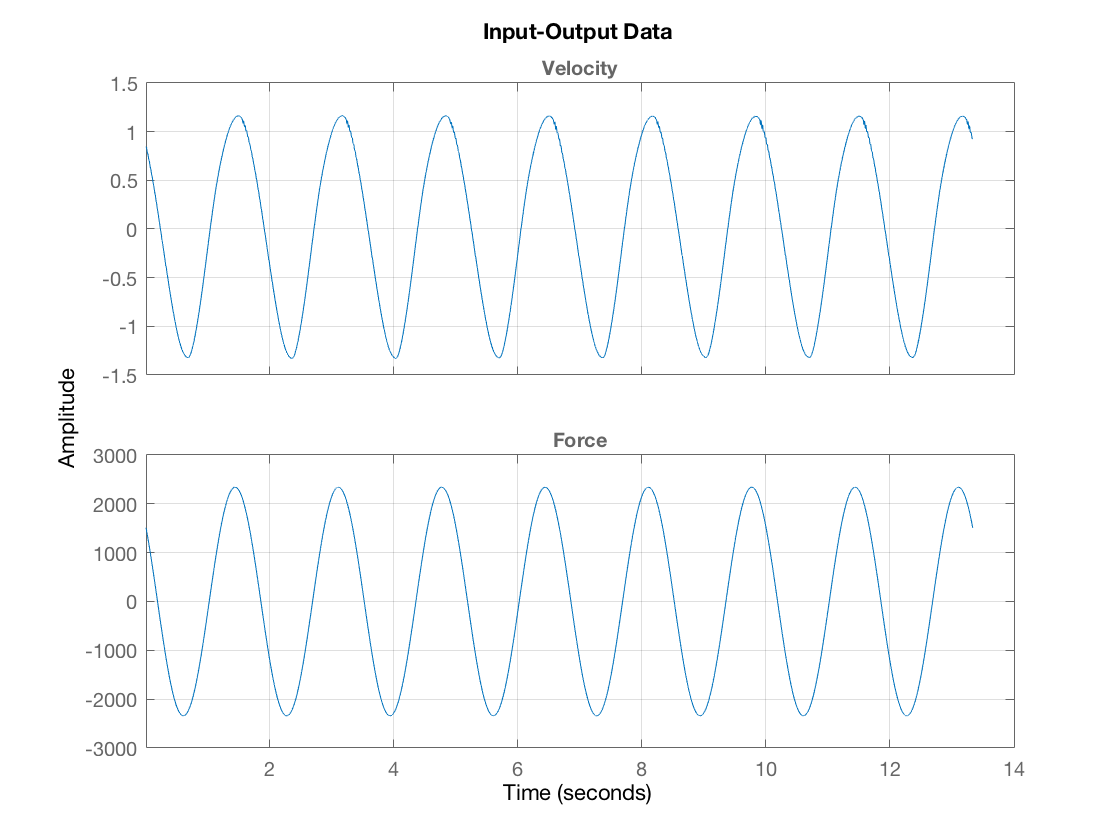

plot(wave_tank_data)
grid on

## Fit linear model

We can fit a linear model (transfer function) to the data.

np = 2; % 2
nz = 1; % 1
TF = tfest(wave_tank_data,np,nz)

TF =
 
  From input "Force" to output "Velocity":
   0.02317 s + 0.5316
  ---------------------
  s^2 + 92.23 s + 987.2
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                    
Estimated using TFEST on time domain data "wave_tank_data".
Fit to estimation data: 92.46%                             
FPE: 0.004255, MSE: 0.004251                               


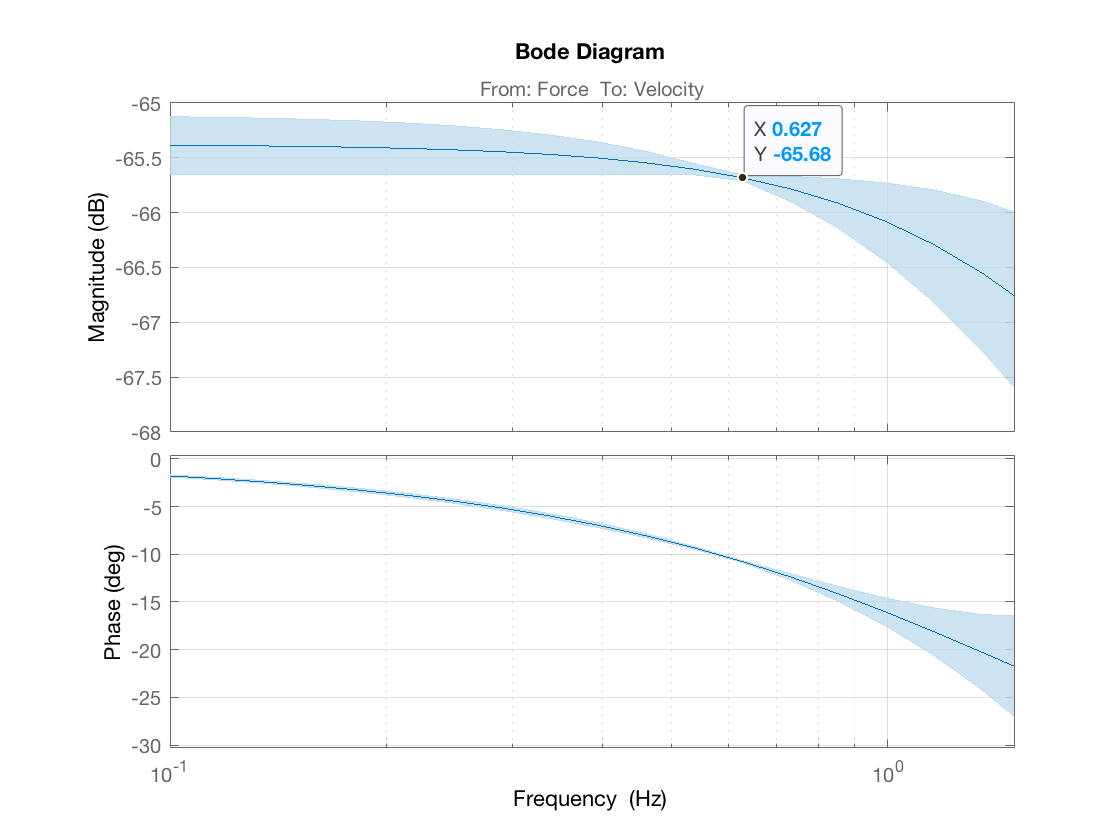

h = bodeplot(TF);
setoptions(h,'FreqUnits','Hz','Grid','on')
showConfidence(h)
xlim([0.1, 1.5])

## Assess model

Now let's look at how the model compares with the data.

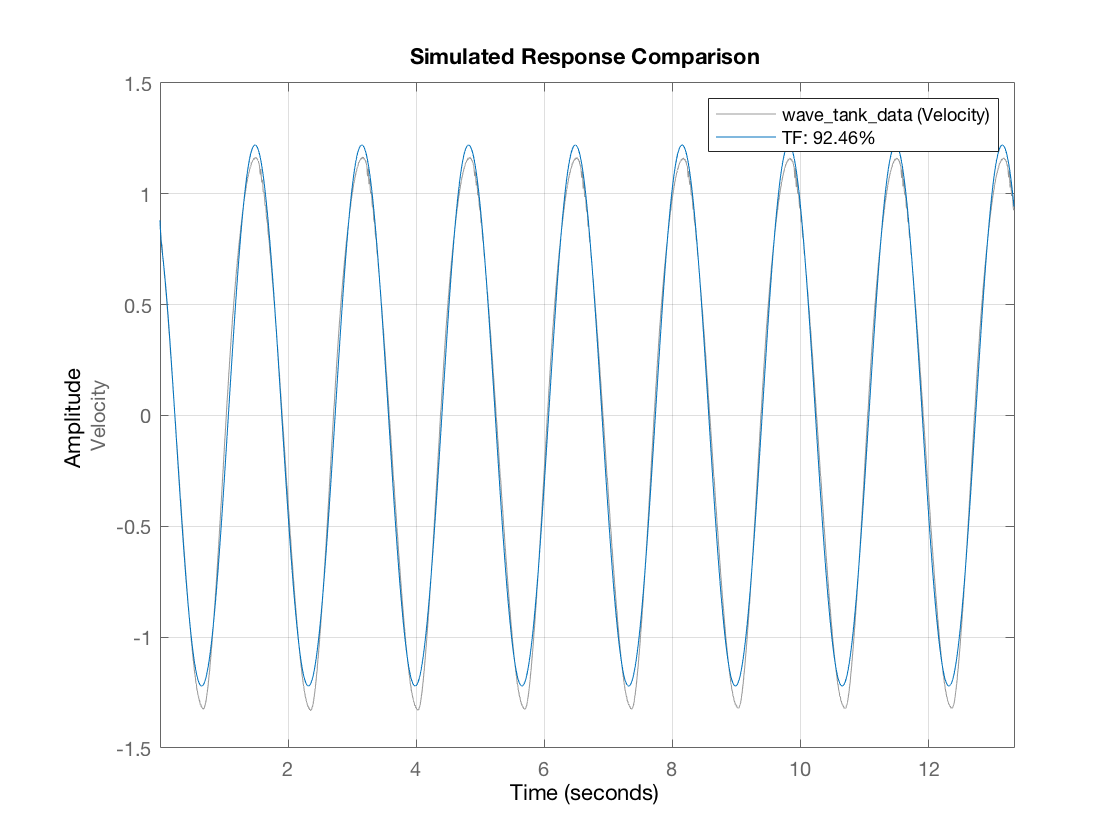

compare(wave_tank_data,TF)
grid on

We can quantify the amount of nonlinearity in the system by calculating the total harmonic distortion (THD). In this case, the nonlinear components of the dynamics contribute to about 7%.

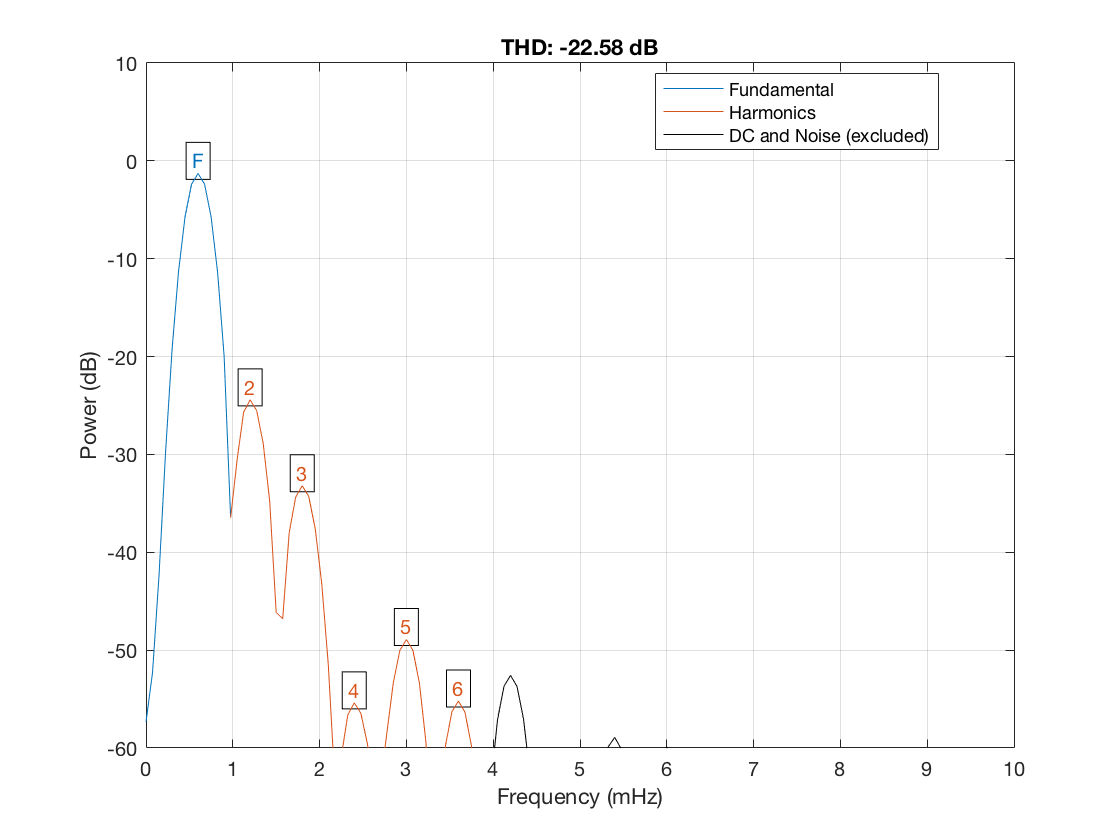

thd(wave_tank_data.OutputData);
xlim([0,10])

[1] Ryan G. Coe, Giorgio Bacelli, Steven J. Spencer, Dominic Forbush, and Kevin Dullea. Advanced WEC dynamics and controls MASK3 test. Technical Report SAND2019-15428, Sandia National Laboratories, Albuquerque, New Mexico, 12 2019a. URL [https://www.osti.gov/biblio/1592850-advanced-wec- dynamics-controls-mask3-test](https://www.osti.gov/biblio/1592850-advanced-wec- dynamics-controls-mask3-test)

% ---------------------------------------------------------------------
% Copyright 2020 National Technology & Engineering Solutions of Sandia,
% LLC (NTESS). Under the terms of Contract DE-NA0003525 with NTESS, the
% U.S. Government retains certain rights in this software.
%
% This file is part of fbWecCntrl.
%
%     fbWecCntrl is free software: you can redistribute it and/or
%     modify it under the terms of the GNU General Public License as
%     published by the Free Software Foundation, either version 3 of
%     the License, or (at your option) any later version.
%
%     fbWecCntrl is distributed in the hope that it will be useful, but
%     WITHOUT ANY WARRANTY; without even the implied warranty of
%     MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU
%     General Public License for more details.
%
%     You should have received a copy of the GNU General Public License
%     along with fbWecCntrl.  If not, see
%     <https://www.gnu.org/licenses/>.
% ---------------------------------------------------------------------